
omega1 = 50;    
omega2 = 60;   
Rp = 3;         
As = 30;       
omega0 = omega2 / omega1;
epsilon = sqrt(10^(Rp/10) - 1);
F = sqrt((10^(As/10) - 1) / (10^(Rp/10) - 1));

N_temp = acosh(F) / acosh(omega0);  
N = ceil(N_temp);

fprintf('Computed filter order N = %d\n', N);

Computed filter order N = 7


fprintf('Computed ripple factor epsilon = %f\n', epsilon);

Computed ripple factor epsilon = 0.997628


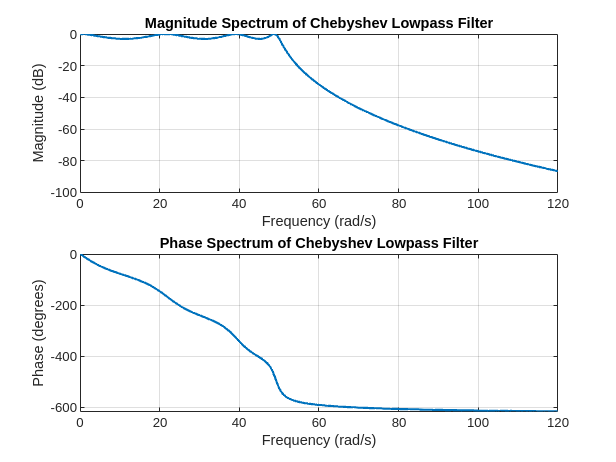



beta = asinh(1/epsilon) / N; 
p_all = [];  
for k = 0:(2*N - 1)
    alpha = (2*k + 1) * pi / (2 * N);
   
    pk = 1i * omega1 * (cos(alpha) * cosh(beta) - 1i * sin(alpha) * sinh(beta));
    p_all = [p_all; pk];
end

p = p_all(real(p_all) < 0);

if length(p) ~= N
    error('Unexpected number of stable poles. Check the calculations.');
end

K = prod(-p);
den = poly(p); 
num = K;       

w = linspace(0, 2*omega2, 1000); 
H = freqs(num, den, w);

figure;

subplot(2,1,1);
plot(w, 20*log10(abs(H)), 'LineWidth', 1.5);
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Magnitude Spectrum of Chebyshev Lowpass Filter');
grid on;

subplot(2,1,2);
plot(w, unwrap(angle(H)) * (180/pi), 'LineWidth', 1.5);
xlabel('Frequency (rad/s)');
ylabel('Phase (degrees)');
title('Phase Spectrum of Chebyshev Lowpass Filter');
grid on;


omega1 = 50;    
Rp = 3;         
N = 7;         

epsilon = sqrt(10^(Rp/10) - 1);
fprintf('Computed ripple factor epsilon = %f\n', epsilon);

Computed ripple factor epsilon = 0.997628


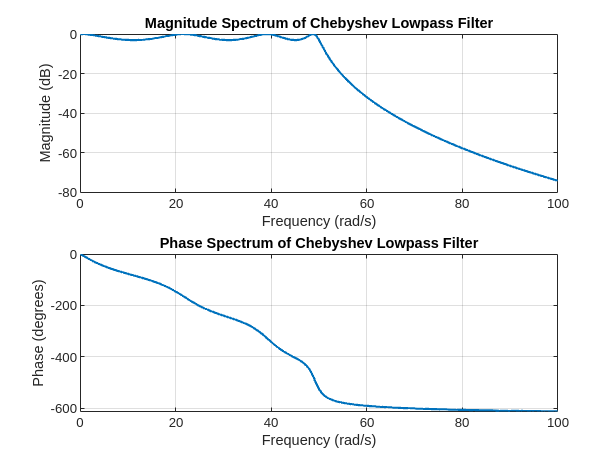


beta = asinh(1/epsilon) / N;
p_all = [];

for k = 0:(2*N - 1)
    alpha = (2*k + 1) * pi / (2 * N);
    pk = 1i * omega1 * (cos(alpha)*cosh(beta) - 1i*sin(alpha)*sinh(beta));
    p_all = [p_all; pk];
end

p = p_all(real(p_all) < 0);
if length(p) ~= N
    error('Unexpected number of stable poles. Check the calculations.');
end

K = prod(-p);
den = poly(p); 
num = K;       

w = linspace(0, 2*omega1, 1000);  
H = freqs(num, den, w);           

figure;

subplot(2,1,1);
plot(w, 20*log10(abs(H)), 'LineWidth', 1.5);
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Magnitude Spectrum of Chebyshev Lowpass Filter');
grid on;

subplot(2,1,2);
plot(w, unwrap(angle(H)) * (180/pi), 'LineWidth', 1.5);
xlabel('Frequency (rad/s)');
ylabel('Phase (degrees)');
title('Phase Spectrum of Chebyshev Lowpass Filter');
grid on;

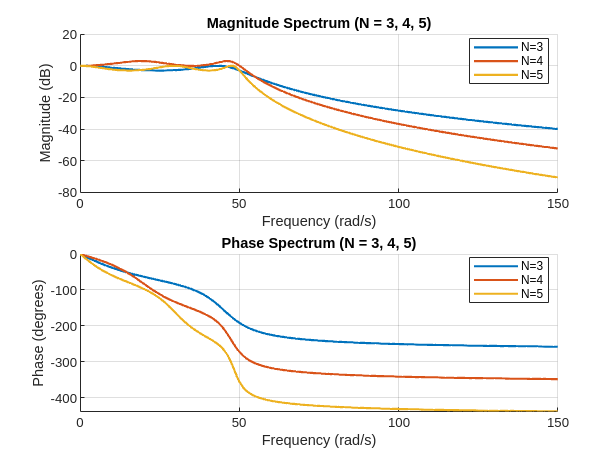


clear; clc; close all;
omega1 = 50;    
Rp = 3;          
epsilon = sqrt(10^(Rp/10) - 1); 

w = linspace(0, 3*omega1, 1000); 
figure('Name','Chebyshev Comparison: N = 3, 4, 5');

subplot(2,1,1);
hold on; grid on;
title('Magnitude Spectrum (N = 3, 4, 5)');
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');

for N = [3, 4, 5]
    beta = asinh(1/epsilon) / N;
    p_all = [];
    for k = 0:(2*N - 1)
        alpha_k = (2*k + 1)*pi/(2*N);
        pk = 1i*omega1*(cos(alpha_k)*cosh(beta) - 1i*sin(alpha_k)*sinh(beta));
        p_all = [p_all; pk];
    end
    p = p_all(real(p_all) < 0);
    K = prod(-p);
    den = poly(p);
    num = K;

    H = freqs(num, den, w);
    plot(w, 20*log10(abs(H)), 'DisplayName', sprintf('N=%d', N), 'LineWidth',1.5);
end

legend('Location','best');

subplot(2,1,2);
hold on; grid on;
title('Phase Spectrum (N = 3, 4, 5)');
xlabel('Frequency (rad/s)');
ylabel('Phase (degrees)');

for N = [3, 4, 5]
   
    beta = asinh(1/epsilon) / N;
    p_all = [];
    for k = 0:(2*N - 1)
        alpha_k = (2*k + 1)*pi/(2*N);
        pk = 1i*omega1*(cos(alpha_k)*cosh(beta) - 1i*sin(alpha_k)*sinh(beta));
        p_all = [p_all; pk];
    end
    p = p_all(real(p_all) < 0);
    K = prod(-p);
    den = poly(p);
    num = K;
    H = freqs(num, den, w);
    plot(w, unwrap(angle(H))*180/pi, 'DisplayName', sprintf('N=%d', N), 'LineWidth',1.5);
end

legend('Location','best');

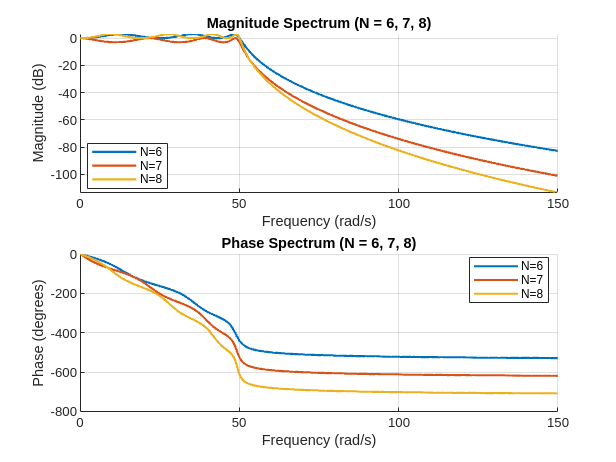


figure('Name','Chebyshev Comparison: N = 6, 7, 8');

subplot(2,1,1);
hold on; grid on;
title('Magnitude Spectrum (N = 6, 7, 8)');
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');

for N = [6, 7, 8]
    beta = asinh(1/epsilon) / N;
    p_all = [];
    for k = 0:(2*N - 1)
        alpha_k = (2*k + 1)*pi/(2*N);
        pk = 1i*omega1*(cos(alpha_k)*cosh(beta) - 1i*sin(alpha_k)*sinh(beta));
        p_all = [p_all; pk];
    end
    p = p_all(real(p_all) < 0);
    K = prod(-p);
    den = poly(p);
    num = K;
    H = freqs(num, den, w);

    plot(w, 20*log10(abs(H)), 'DisplayName', sprintf('N=%d', N), 'LineWidth',1.5);
end
legend('Location','best');

subplot(2,1,2);
hold on; grid on;
title('Phase Spectrum (N = 6, 7, 8)');
xlabel('Frequency (rad/s)');
ylabel('Phase (degrees)');

for N = [6, 7, 8]
    beta = asinh(1/epsilon) / N;
    p_all = [];
    for k = 0:(2*N - 1)
        alpha_k = (2*k + 1)*pi/(2*N);
        pk = 1i*omega1*(cos(alpha_k)*cosh(beta) - 1i*sin(alpha_k)*sinh(beta));
        p_all = [p_all; pk];
    end
    p = p_all(real(p_all) < 0);
    K = prod(-p);
    den = poly(p);
    num = K;
    H = freqs(num, den, w);

    plot(w, unwrap(angle(H))*180/pi, 'DisplayName', sprintf('N=%d', N), 'LineWidth',1.5);
end
legend('Location','best');

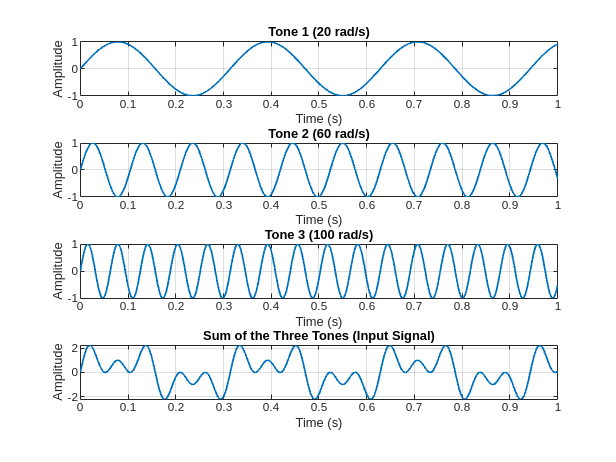



clear; clc; close all;

dt = 1e-3;   
tEnd = 1.0;    
t = (0:dt:tEnd).';  

tone1 = sin(20*t);
tone2 = sin(60*t);
tone3 = sin(100*t);
x = tone1 + tone2 + tone3; 

figure('Name','Individual Tones and Their Sum');
subplot(4,1,1);
plot(t, tone1, 'LineWidth',1.2); grid on;
xlabel('Time (s)'); ylabel('Amplitude');
title('Tone 1 (20 rad/s)');

subplot(4,1,2);
plot(t, tone2, 'LineWidth',1.2); grid on;
xlabel('Time (s)'); ylabel('Amplitude');
title('Tone 2 (60 rad/s)');

subplot(4,1,3);
plot(t, tone3, 'LineWidth',1.2); grid on;
xlabel('Time (s)'); ylabel('Amplitude');
title('Tone 3 (100 rad/s)');

subplot(4,1,4);
plot(t, x, 'LineWidth',1.2); grid on;
xlabel('Time (s)'); ylabel('Amplitude');
title('Sum of the Three Tones (Input Signal)');

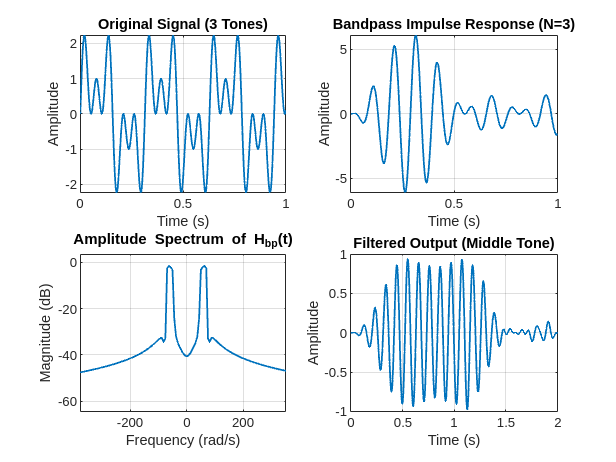

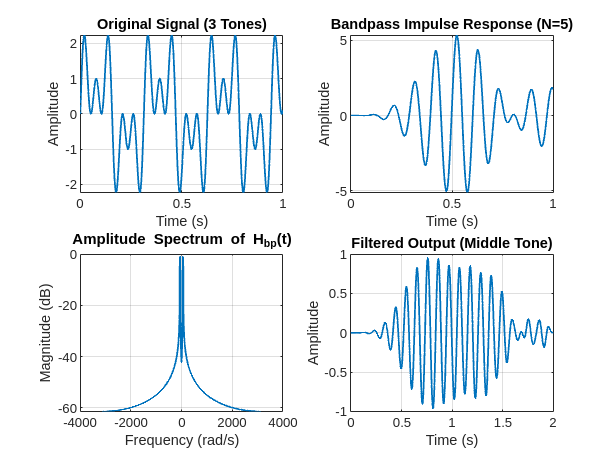

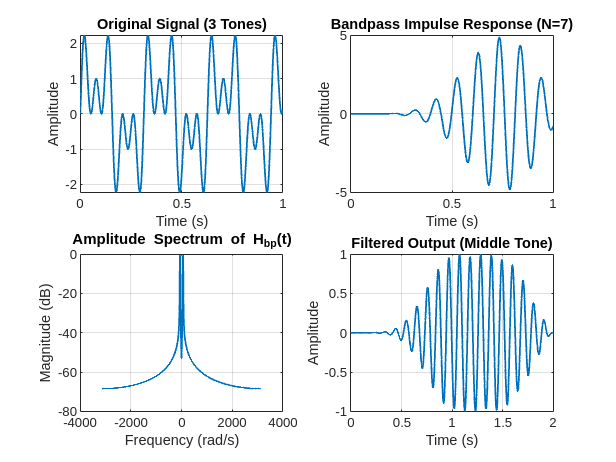


omega_mid = 60; 
BW = 20;       
omega_lp = BW/2;

Rp = 3;
orders = [3, 5, 7];

for N = orders
    
    figure('Name', sprintf('Chebyshev Bandpass Filter (N=%d)', N));
    h_lp = chebyLowpassImpulse(N, omega_lp, Rp, t);
    h_bp = 2 * h_lp .* cos(omega_mid * t);

    x_col = x(:);       
    h_bp_col = h_bp(:); 
    y = conv(x_col, h_bp_col) * dt; 
    t_y = (0:length(y)-1).' * dt;   
    subplot(2,2,1);
    plot(t, x, 'LineWidth',1.2);
    grid on; xlabel('Time (s)'); ylabel('Amplitude');
    title('Original Signal (3 Tones)');

    subplot(2,2,2);
    plot(t, h_bp, 'LineWidth',1.2);
    grid on; xlabel('Time (s)'); ylabel('Amplitude');
    title(sprintf('Bandpass Impulse Response (N=%d)', N));

    L = length(h_bp_col);
    Hf = fft(h_bp_col)*dt;    
    Hf_shift = fftshift(Hf);   
    df_rad = 2*pi/(L*dt);       
    
    freqAxisShift = (-floor(L/2) : ceil(L/2)-1).' * df_rad;
    
    subplot(2,2,3);
    plot(freqAxisShift, 20*log10(abs(Hf_shift)), 'LineWidth',1.2);
    grid on; xlabel('Frequency (rad/s)'); ylabel('Magnitude (dB)');
    title('Amplitude Spectrum of H_{bp}(t)');

    subplot(2,2,4);
    plot(t_y, y, 'LineWidth',1.2);
    grid on; xlabel('Time (s)'); ylabel('Amplitude');
    title('Filtered Output (Middle Tone)');
    
end


function h_lp = chebyLowpassImpulse(N, W, Rp, t)

    epsilon = sqrt(10^(Rp/10) - 1);
    beta = asinh(1/epsilon)/N;
    p_all = [];
    for k = 0:(2*N - 1)
        alpha_k = (2*k+1)*pi/(2*N);
        pk = 1i*W * (cos(alpha_k)*cosh(beta) - 1i*sin(alpha_k)*sinh(beta));
        p_all = [p_all; pk];
    end
    
    p = p_all(real(p_all)<0);
    if length(p) ~= N
        error('Unexpected number of stable poles: check design.');
    end

    K = prod(-p);
    den = poly(p);
    den = real(den);
    num = real(K);
    sys_lp = tf(num, den);
    hData = impulse(sys_lp, t);
    h_lp = squeeze(hData);
end
